%Clear
clear all,close all,clc

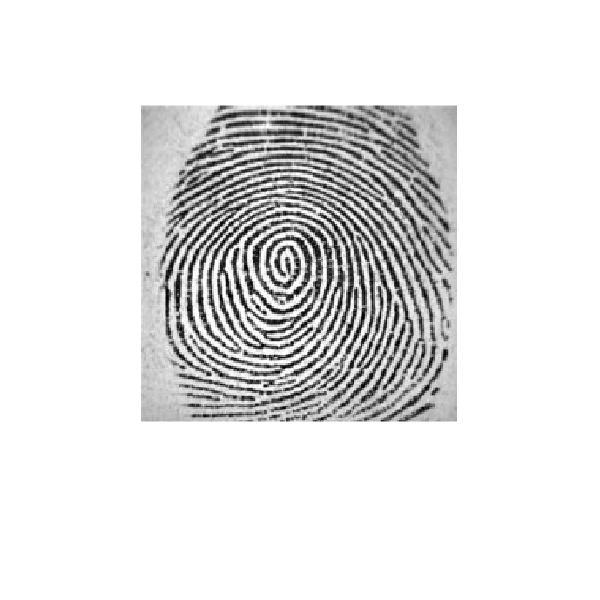


%Loading Image
I=imread('Empreinte.bmp');
imshow(I)
%figure size change
set(gcf,'position',[1 1 600 600]);

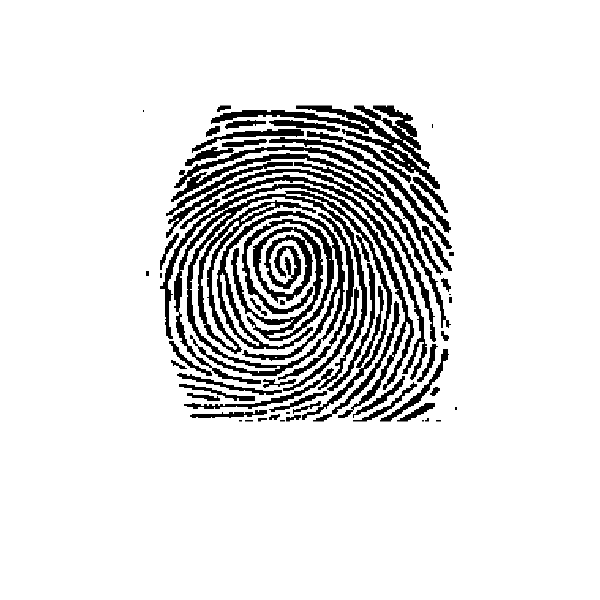


%Image Enhancement is not needed as the image quality is good

%Binarization
J=I(:,:,1)>160;
imshow(J)
set(gcf,'position',[1 1 600 600]);

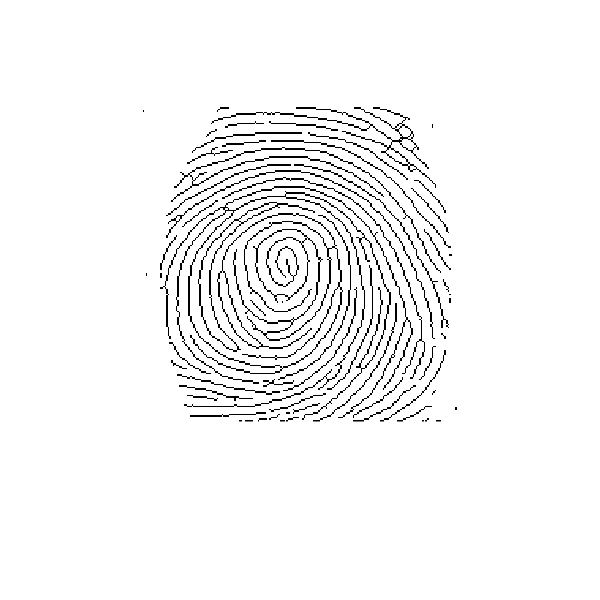


%Thining
K=bwmorph(~J,'thin','inf');
imshow(~K)
set(gcf,'position',[1 1 600 600]);

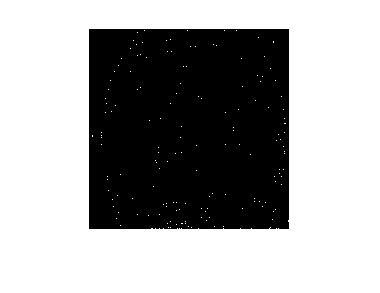


%Minutiae Finding
fun=@minutie;
L = nlfilter(K,[3 3],fun);
%Termination
LTerm=(L==1);
imshow(LTerm)

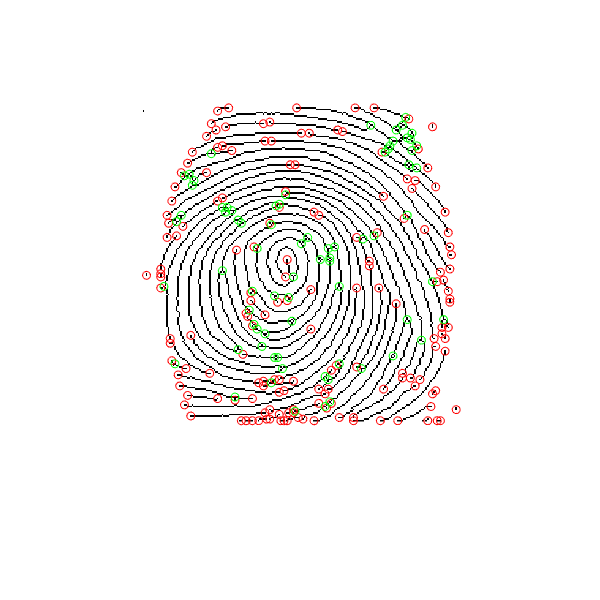

LTermLab=bwlabel(LTerm);
propTerm=regionprops(LTermLab,'Centroid');
CentroidTerm=round(cat(1,propTerm(:).Centroid));
imshow(~K)
set(gcf,'position',[1 1 600 600]);
hold on
plot(CentroidTerm(:,1),CentroidTerm(:,2),'ro')
%Bifurcation
LBif=(L==3);
LBifLab=bwlabel(LBif);
propBif=regionprops(LBifLab,'Centroid','Image');
CentroidBif=round(cat(1,propBif(:).Centroid));
plot(CentroidBif(:,1),CentroidBif(:,2),'go')


%Removing useless minutiae
D=6;
%Process_1(if the distance between a termination and a biffurcation is smaller than D)
Distance=DistEuclidian(CentroidBif,CentroidTerm);
SpuriousMinutae=Distance<D;
[i,j]=find(SpuriousMinutae);
CentroidBif(i,:)=[];
CentroidTerm(j,:)=[];
%Process_2(if the distance between two biffurcations is smaller than D)
Distance=DistEuclidian(CentroidBif);
SpuriousMinutae=Distance<D;
[i,j]=find(SpuriousMinutae);
CentroidBif(i,:)=[];
%Process_3(if the distance between two terminations is smaller than D)
hold off

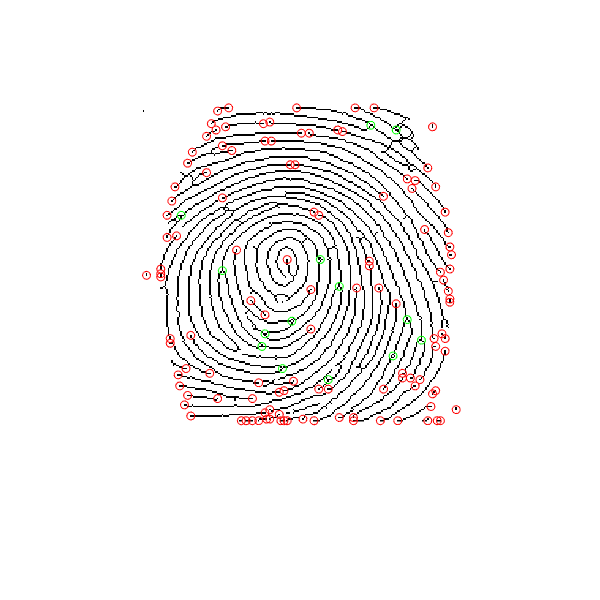

imshow(~K)
hold on
plot(CentroidTerm(:,1),CentroidTerm(:,2),'ro')
plot(CentroidBif(:,1),CentroidBif(:,2),'go')
hold off

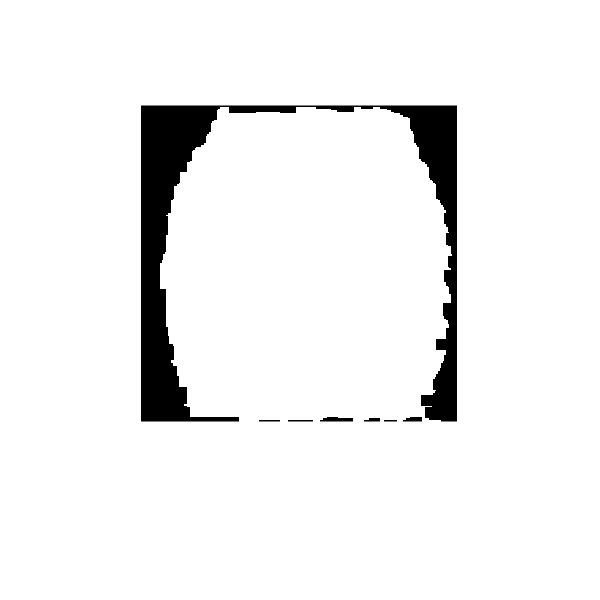


%Choosing ROI
Kopen=imclose(K,strel('square',7));
KopenClean= imfill(Kopen,'holes');
KopenClean=bwareaopen(KopenClean,5);
imshow(KopenClean)

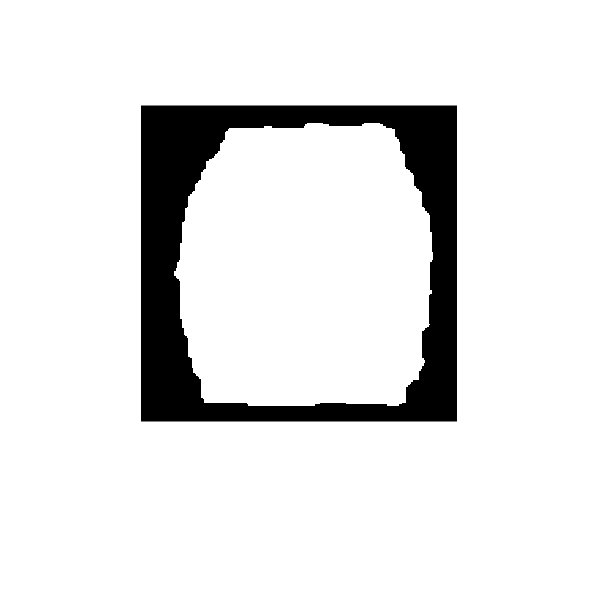

KopenClean([1 end],:)=0;
KopenClean(:,[1 end])=0;
ROI=imerode(KopenClean,strel('disk',10));
imshow(ROI)

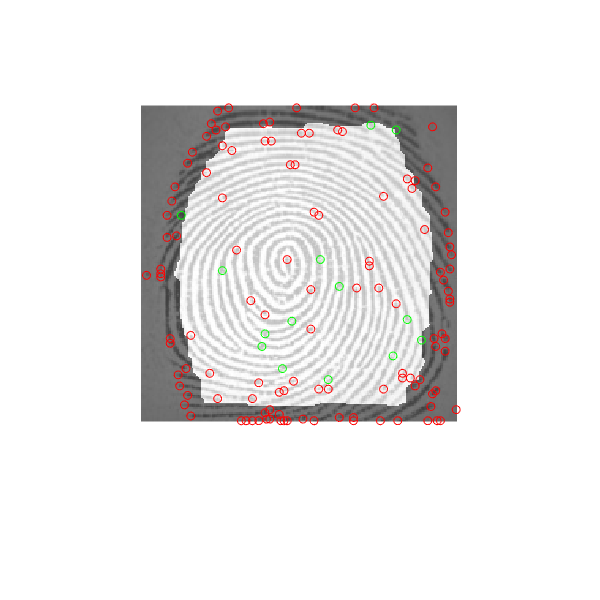

imshow(I)
hold on
imshow(ROI)
alpha(0.5)
hold on
plot(CentroidTerm(:,1),CentroidTerm(:,2),'ro')
plot(CentroidBif(:,1),CentroidBif(:,2),'go')
hold off

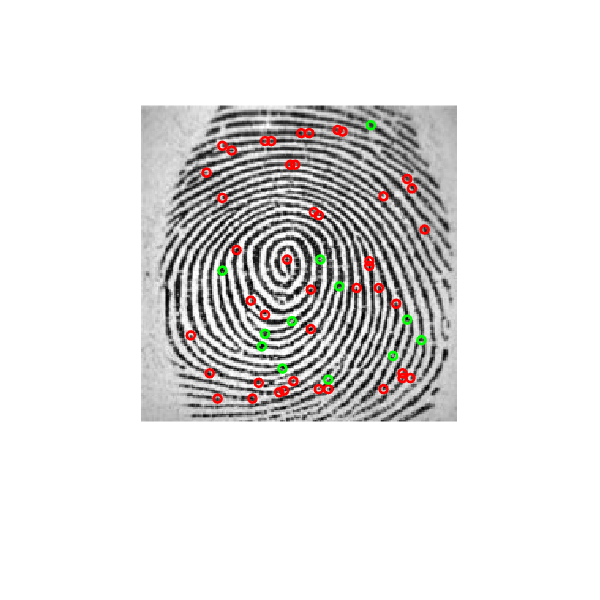


%Suppressng Extreme Minutiae
[m,n]=size(I(:,:,1));
indTerm= sub2ind([m,n],CentroidTerm(:,1),CentroidTerm(:,2));
Z=zeros(m,n);
Z(indTerm)=1;
ZTerm=Z.*ROI';
[CentroidTermX,CentroidTermY]=find(ZTerm);
indBif=sub2ind([m,n],CentroidBif(:,1),CentroidBif(:,2));
Z=zeros(m,n);
Z(indBif)=1;
ZBif=Z.*ROI';
[CentroidBifX,CentroidBifY]=find(ZBif);
imshow(I)
hold on
plot(CentroidTermX,CentroidTermY,'ro','linewidth',2)
plot(CentroidBifX,CentroidBifY,'go','linewidth',2)

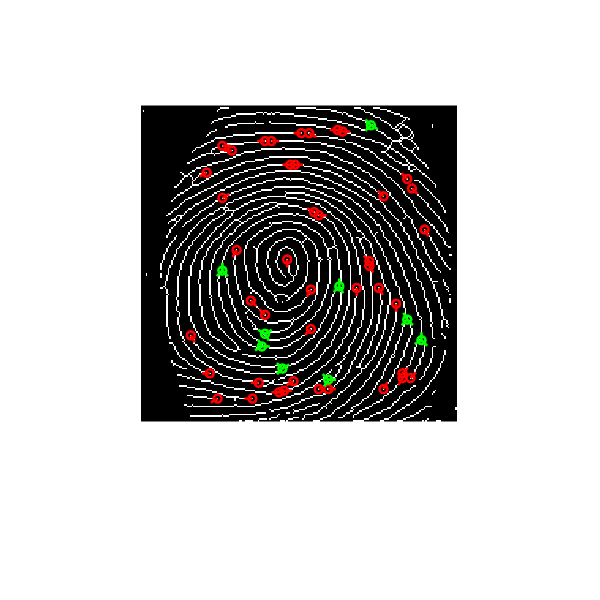


%Orientation of Minutiae Point
Table=[3*pi/4 2*pi/3 pi/2 pi/3 pi/4
    5*pi/6 0 0 0 pi/6
    pi 0 0 0 0
    -5*pi/6 0 0 0 -pi/6
    -3*pi/4 -2*pi/3 -pi/2 -pi/3 -pi/4];
%Termination Orientation
for ind=1:length(CentroidTermX)
    Klocal=K(CentroidTermY(ind)-2:CentroidTermY(ind)+2,CentroidTermX(ind)-2:CentroidTermX(ind)+2);
    Klocal(2:end-1,2:end-1)=0;
    [i,j]=find(Klocal);
    OrientationTerm(ind,1)=Table(i(1,:),j(1,:));
end
dxTerm=sin(OrientationTerm)*5;
dyTerm=cos(OrientationTerm)*5;
figure
imshow(K)
set(gcf,'position',[1 1 600 600]);
hold on
plot(CentroidTermX,CentroidTermY,'ro','linewidth',2)
plot([CentroidTermX CentroidTermX+dyTerm]',...
    [CentroidTermY CentroidTermY-dxTerm]','r','linewidth',2)

%Bifurcation Orientation
for ind=1:length(CentroidBifX)
    Klocal=K(CentroidBifY(ind)-2:CentroidBifY(ind)+2,CentroidBifX(ind)-2:CentroidBifX(ind)+2);
    Klocal(2:end-1,2:end-1)=0;
    [i,j]=find(Klocal);
    if length(i)~=3
        CentroidBifY(ind)=NaN;
        CentroidBifX(ind)=NaN;
        OrientationBif(ind)=NaN;
    else
        for k=1:3
            OrientationBif(ind,k)=Table(i(k),j(k));
            dxBif(ind,k)=sin(OrientationBif(ind,k))*5;
            dyBif(ind,k)=cos(OrientationBif(ind,k))*5;
            
        end
    end
end

plot(CentroidBifX,CentroidBifY,'go','linewidth',2)
OrientationLinesX=[CentroidBifX CentroidBifX+dyBif(:,1);CentroidBifX CentroidBifX+dyBif(:,2);CentroidBifX CentroidBifX+dyBif(:,3)]';
OrientationLinesY=[CentroidBifY CentroidBifY-dxBif(:,1);CentroidBifY CentroidBifY-dxBif(:,2);CentroidBifY CentroidBifY-dxBif(:,3)]';
plot(OrientationLinesX,OrientationLinesY,'g','linewidth',2)

% user defined Random points
Kx = 82;
Ky = 56;


%Computing the distance between the features and random point 

for w=1:12
    
    EuDistance(w) = sqrt(((CentroidBifX(w)-Kx).^2)+((CentroidBifY(w)-Ky).^2));
    
       
end

%Median filter
MedianFilter = medfilt1(EuDistance);

RDM = rmmissing(MedianFilter);

save('rdmvalues.mat','RDM')